# Make RTM images for different velocity anomalies

**Author**: Ivan Abakumov

**Publication date**: 24th August 2018

**E-mail**: abakumov_ivan@mail.ru

**Task**: perform RTM for OBN data for our 4 models: 

- traveltime tomo

- FWI on diving waves

- FWI + reflections

- FWI + reflection and diffractions

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;


## Apply inversion settings

INV_settings;

thisfolder = '/home/ivan/Desktop/MLIB/Examples/Paper_Role_of_diffractions_in_velocity_model_building'

## Upload velocity models

% tomo
dV_tomo = zeros(G.nx, G.nz); 
dV_tomo(target.xx,target.zz) = MLD('/home/ivan/Desktop/FWI_DIFF/result/TOMO/TOMO_First_dv_111.mat');
dV_tomo = SME(dV_tomo,1);

% FWI diving only
dV_fwi_diving = zeros(G.nx, G.nz); 
dV_fwi_diving(target.xx,target.zz) = MLD('/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_only/FWI_First_dv_55.mat');
dV_fwi_diving = SME(dV_fwi_diving,1);

% FWI diving + reflected

dV_fwi_ref = zeros(G.nx, G.nz); 
dV_fwi_ref(target.xx,target.zz) = MLD('/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_ref_diff/FWI_First_dv_39.mat');
dV_fwi_ref = SME(dV_fwi_ref,1);

% FWI diving + reflected + diffracted

dV_fwi_dif = zeros(G.nx, G.nz); 
dV_fwi_dif(target.xx,target.zz) = MLD('/home/ivan/Desktop/FWI_DIFF/result/FWI_diving_ref_diff/FWI_First_dv_59.mat');
dV_fwi_dif = SME(dV_fwi_dif,1);

% True anomaly
dV_true = mvelmod-bvelmod;
dV_true = SME(dV_true,1);


## Plot velocity models

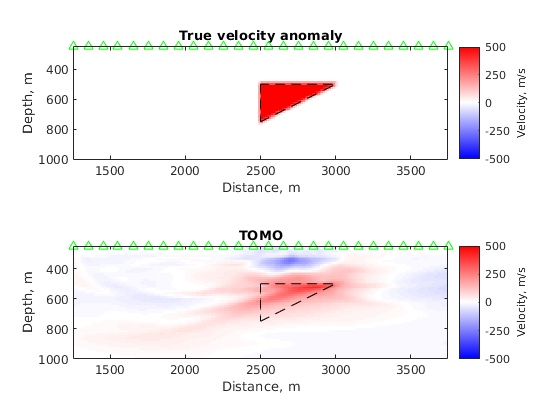

% TOMO

figure(1)
subplot(2,1,1)
imagesc(G.xx, G.zz,  dV_true')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
imagesc(G.xx, G.zz, dV_tomo')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
title('TOMO')

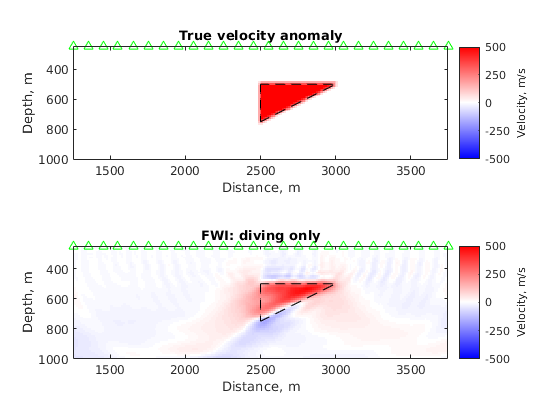



% FWI (no diffractions)

figure(2)
subplot(2,1,1)
imagesc(G.xx, G.zz,  dV_true')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
imagesc(G.xx, G.zz, dV_fwi_diving')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
title('FWI: diving only')

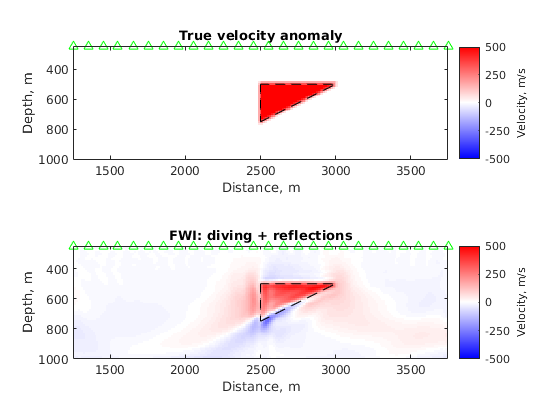



% FWI diving and reflections

figure(3)
subplot(2,1,1)
imagesc(G.xx, G.zz,  dV_true')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
imagesc(G.xx, G.zz, dV_fwi_ref')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
title('FWI: diving + reflections')

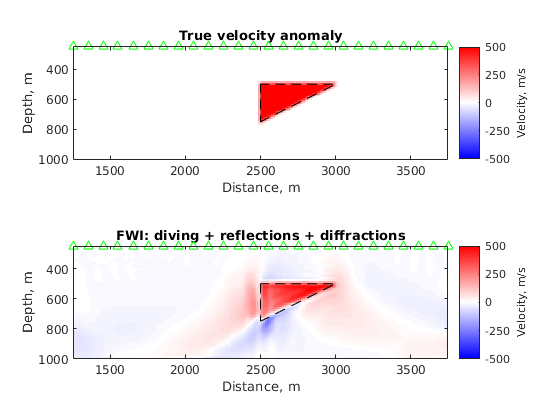


% FWI, diving + reflections + diffractions

figure(4)
subplot(2,1,1)
imagesc(G.xx, G.zz,  dV_true')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('True velocity anomaly')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)
imagesc(G.xx, G.zz, dV_fwi_dif')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--black', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--black', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--black', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
caxis([-500, 500])
axis([1250 3750 250 1000]); 
c = colorbar('Ticks', [-500,-250,0,250,500]);
c.Label.String = 'Velocity, m/s';
xlabel('Distance, m')
ylabel('Depth, m')
title('FWI: diving + reflections + diffractions')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

## Make RTM image for different velocities

fpeak = 20; 

VV = zeros(G.nx, G.nz, 5); 
VV(:,:,1) = dV_tomo;
VV(:,:,2) = dV_fwi_diving;
VV(:,:,3) = dV_fwi_ref;
VV(:,:,4) = dV_fwi_dif;
VV(:,:,5) = dV_true;

RRTM = zeros(length(target.xx), length(target.zz), 5); 

for vv = 5:5

    INV_settings; 
    
    bvelmod =  bvelmod + squeeze(VV(:,:,vv)); 
 
    RTM = zeros(length(target.xx), length(target.zz)); 

    for ishot=1:nthreads:length(acq.sx)

        shotnum = ishot:min(length(acq.sx), ishot+nthreads-1); 

         % baseline
         [f09,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, bvelmod);
         s09 = zeros(length(acq.rx), G.nt, length(shotnum));
         for s=1:length(shotnum)
             for i=1:length(acq.rx)
                 s09(i, :, s) = f09(acq.grx(i),acq.grz(i),:,s);
             end
         end
         U = f09(target.xx,target.zz,:,:);  
         clear f09; 

         % monitor 
         [f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, mvelmod);
         s10 = zeros(length(acq.rx), G.nt,length(shotnum));
         for s=1:length(shotnum) 
             for i=1:length(acq.rx)
                 s10(i,:,s) = f10(acq.grx(i),acq.grz(i),:,s);
             end
         end
         clear f10; 

         % inverse seismograms        
         ds = s10; 
         ds = ds(:, end:-1:1,:); 

         % adjoint state
         [q,~,~] = Get_FD_backward(G, acq, shotnum, fpeak, ds, bvelmod);
         Q = q(target.xx,target.zz,:,:);
         clear q

         % functional and gradient
         rtm=make_RTM_LS(G,U,Q);
         clear U Q

         RTM = RTM + rtm;
    end
    
    RRTM(:,:,vv) = RTM;
end

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 13


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 13; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 150; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 240.532734 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 13


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 13; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 150; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 242.086438 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 13


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 13; nb = 401; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 1, stype = 0; wtype = 0; atype=1;
sxi[0] = 50; szi[0] = 100;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 410.804373 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 13


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 13; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 254; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 411.654121 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 13


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 13; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 254; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 239.029828 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 13


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 13; nb = 401; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 1, stype = 0; wtype = 0; atype=1;
sxi[0] = 50; szi[0] = 100;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 242.128326 seconds.


## Apply weight functions

INV_settings;
IMAGE = zeros(501,401,5);

for j = 1:5

    RTM = squeeze(RRTM(:,:,j));
    weight = ones(size(RTM));
    for i=1:201
        weight(i,1:41) = atan(exp(-6:.3:6))/pi*2;
    end
         
    velmod = bvelmod + VV(:,:,j);
    
    IMAGE(target.xx,target.zz,j) = weight.*RTM*10^9./velmod(target.xx,target.zz).^2;

end


## Save images as SEGY file

for j=1:5
    % Save traces as segy file 
    seismic = s_data; 
    seismic.traces = zeros(401, 501); 
    seismic.headers = zeros(2,  501); 

    % change header_info
    seismic.header_info(1,:) = cellstr(['cdp        '; 'no         '; 'cdp        ']);
    seismic.header_info(2,:) = cellstr(['cdp_x      '; 'no         '; 'cdp_x      ']);

    % change traces and headers
    for i=1:501
        seismic.traces(:,  i) = IMAGE(i,:,j);
        seismic.headers(1, i) = G.xx(i)/G.dx+51;
        seismic.headers(2, i) = G.xx(i);
    end

    % change time information
    seismic.first = G.zz(1); 
    seismic.last  = G.zz(401); 
    seismic.step  = G.dz; 

    % change data information 
    seismic.name = cellstr('RTM image');
    seismic.history(1) = cellstr(date);
    seismic.history(2) = cellstr('Abakumov Ivan');
    seismic.history(3) = cellstr('RTM image');

    filename = ['RTM_IMAGE_original_' num2str(j) '.sgy'];

    write_segy_file(seismic, filename);
end

 WARNING! Start time of seismic < 0. Seismic data will be shifted by 1250 ms
A header "LAG" will be written to the SEG-Y file
EBCDIC reel header written


Binary reel header written
Header "ds_seqno" not found in dataset and assumed to be zero
Header "ffid" not found in dataset and assumed to be zero
Header "o_trace_no" not found in dataset and assumed to be zero
Header "source" not found in dataset and assumed to be zero
Header "seq_cdp" not found in dataset and assumed to be zero
Header "trc_type" not found in dataset and assumed to be zero
Header "offset" not found in dataset and assumed to be zero
Header "depth" not found in dataset and assumed to be zero
Header "sou_h2od" not found in dataset and assumed to be zero
Header "rec_h2od" not found in dataset and assumed to be zero
Header "sou_x" not found in dataset and assumed to be zero
Header "sou_y" not found in dataset and assumed to be zero
Header "sou_elev" not found in dataset and assumed to be zero
Header "rec_x" not found in dataset and assumed to be zero
Header "rec_y" not found in dataset and assumed to be zero
Header "rec_elev" not found in dataset and assumed to be zero
Hea

Binary reel header written
Header "ds_seqno" not found in dataset and assumed to be zero
Header "ffid" not found in dataset and assumed to be zero
Header "o_trace_no" not found in dataset and assumed to be zero
Header "source" not found in dataset and assumed to be zero
Header "seq_cdp" not found in dataset and assumed to be zero
Header "trc_type" not found in dataset and assumed to be zero
Header "offset" not found in dataset and assumed to be zero
Header "depth" not found in dataset and assumed to be zero
Header "sou_h2od" not found in dataset and assumed to be zero
Header "rec_h2od" not found in dataset and assumed to be zero
Header "sou_x" not found in dataset and assumed to be zero
Header "sou_y" not found in dataset and assumed to be zero
Header "sou_elev" not found in dataset and assumed to be zero
Header "rec_x" not found in dataset and assumed to be zero
Header "rec_y" not found in dataset and assumed to be zero
Header "rec_elev" not found in dataset and assumed to be zero
Hea

Binary reel header written
Header "ds_seqno" not found in dataset and assumed to be zero
Header "ffid" not found in dataset and assumed to be zero
Header "o_trace_no" not found in dataset and assumed to be zero
Header "source" not found in dataset and assumed to be zero
Header "seq_cdp" not found in dataset and assumed to be zero
Header "trc_type" not found in dataset and assumed to be zero
Header "offset" not found in dataset and assumed to be zero
Header "depth" not found in dataset and assumed to be zero
Header "sou_h2od" not found in dataset and assumed to be zero
Header "rec_h2od" not found in dataset and assumed to be zero
Header "sou_x" not found in dataset and assumed to be zero
Header "sou_y" not found in dataset and assumed to be zero
Header "sou_elev" not found in dataset and assumed to be zero
Header "rec_x" not found in dataset and assumed to be zero
Header "rec_y" not found in dataset and assumed to be zero
Header "rec_elev" not found in dataset and assumed to be zero
Hea

Binary reel header written
Header "ds_seqno" not found in dataset and assumed to be zero
Header "ffid" not found in dataset and assumed to be zero
Header "o_trace_no" not found in dataset and assumed to be zero
Header "source" not found in dataset and assumed to be zero
Header "seq_cdp" not found in dataset and assumed to be zero
Header "trc_type" not found in dataset and assumed to be zero
Header "offset" not found in dataset and assumed to be zero
Header "depth" not found in dataset and assumed to be zero
Header "sou_h2od" not found in dataset and assumed to be zero
Header "rec_h2od" not found in dataset and assumed to be zero
Header "sou_x" not found in dataset and assumed to be zero
Header "sou_y" not found in dataset and assumed to be zero
Header "sou_elev" not found in dataset and assumed to be zero
Header "rec_x" not found in dataset and assumed to be zero
Header "rec_y" not found in dataset and assumed to be zero
Header "rec_elev" not found in dataset and assumed to be zero
Hea

Binary reel header written
Header "ds_seqno" not found in dataset and assumed to be zero
Header "ffid" not found in dataset and assumed to be zero
Header "o_trace_no" not found in dataset and assumed to be zero
Header "source" not found in dataset and assumed to be zero
Header "seq_cdp" not found in dataset and assumed to be zero
Header "trc_type" not found in dataset and assumed to be zero
Header "offset" not found in dataset and assumed to be zero
Header "depth" not found in dataset and assumed to be zero
Header "sou_h2od" not found in dataset and assumed to be zero
Header "rec_h2od" not found in dataset and assumed to be zero
Header "sou_x" not found in dataset and assumed to be zero
Header "sou_y" not found in dataset and assumed to be zero
Header "sou_elev" not found in dataset and assumed to be zero
Header "rec_x" not found in dataset and assumed to be zero
Header "rec_y" not found in dataset and assumed to be zero
Header "rec_elev" not found in dataset and assumed to be zero
Hea

## Appy Gaussian filter (in SU)


!segyread tape=RTM_IMAGE_original_1.sgy > RTM_IMAGE_original_1.su

3200+0 records in
6+1 records out
3200 bytes (3.2 kB) copied, 0.00303393 s, 1.1 MB/s


!segyread tape=RTM_IMAGE_original_2.sgy > RTM_IMAGE_original_2.su     

3200+0 records in
6+1 records out
3200 bytes (3.2 kB) copied, 0.00427088 s, 749 kB/s


!segyread tape=RTM_IMAGE_original_3.sgy > RTM_IMAGE_original_3.su     

3200+0 records in
6+1 records out
3200 bytes (3.2 kB) copied, 0.00328903 s, 973 kB/s


!segyread tape=RTM_IMAGE_original_4.sgy > RTM_IMAGE_original_4.su     

3200+0 records in
6+1 records out
3200 bytes (3.2 kB) copied, 0.00315208 s, 1.0 MB/s


!segyread tape=RTM_IMAGE_original_5.sgy > RTM_IMAGE_original_5.su   

3200+0 records in
6+1 records out
3200 bytes (3.2 kB) copied, 0.00320779 s, 998 kB/s



!sukfrac < RTM_IMAGE_original_1.su  power=2 phasefac=-1 d1=12.5 d2=12.5  > RTM_IMAGE_filtered_1.su


sukfrac: tr.trid = 0


!sukfrac < RTM_IMAGE_original_2.su  power=2 phasefac=-1 d1=12.5 d2=12.5  > RTM_IMAGE_filtered_2.su


sukfrac: tr.trid = 0


!sukfrac < RTM_IMAGE_original_3.su  power=2 phasefac=-1 d1=12.5 d2=12.5  > RTM_IMAGE_filtered_3.su


sukfrac: tr.trid = 0


!sukfrac < RTM_IMAGE_original_4.su  power=2 phasefac=-1 d1=12.5 d2=12.5  > RTM_IMAGE_filtered_4.su


sukfrac: tr.trid = 0


!sukfrac < RTM_IMAGE_original_5.su  power=2 phasefac=-1 d1=12.5 d2=12.5  > RTM_IMAGE_filtered_5.su


sukfrac: tr.trid = 0



!segyhdrs < RTM_IMAGE_filtered_1.su > RTM_IMAGE_filtered_hdrs_1.su

!segywrite < RTM_IMAGE_filtered_1.su tape=RTM_IMAGE_filtered_1.sgy

!segyhdrs < RTM_IMAGE_filtered_2.su > RTM_IMAGE_filtered_hdrs_2.su

!segywrite < RTM_IMAGE_filtered_2.su tape=RTM_IMAGE_filtered_2.sgy

!segyhdrs < RTM_IMAGE_filtered_3.su > RTM_IMAGE_filtered_hdrs_3.su

!segywrite < RTM_IMAGE_filtered_3.su tape=RTM_IMAGE_filtered_3.sgy

!segyhdrs < RTM_IMAGE_filtered_4.su > RTM_IMAGE_filtered_hdrs_4.su

!segywrite < RTM_IMAGE_filtered_4.su tape=RTM_IMAGE_filtered_4.sgy

!segyhdrs < RTM_IMAGE_filtered_5.su > RTM_IMAGE_filtered_hdrs_5.su

!segywrite < RTM_IMAGE_filtered_5.su tape=RTM_IMAGE_filtered_5.sgy


!rm -f *su

!rm -f header

!rm -f binary

## Plot final result (for paper)

FIMAGE = zeros(501,401,5);

folder = [mlibfolder '/Examples/Paper_Role_of_diffractions_in_velocity_model_building/result/RTM'];
for j = 1:5

    filename = [folder '/RTM_IMAGE_filtered_' num2str(j) '.sgy'];
    
    segydata = read_segy_file(filename);
    FIMAGE(:,:,j) = segydata.traces';

end

Seismic data shifted since header "lag" is not identically zero.
Lag varies from -1250 to -1250
Seismic data shifted since header "lag" is not identically zero.
Lag varies from -1250 to -1250
Seismic data shifted since header "lag" is not identically zero.
Lag varies from -1250 to -1250
Seismic data shifted since header "lag" is not identically zero.
Lag varies from -1250 to -1250
Seismic data shifted since header "lag" is not identically zero.
Lag varies from -1250 to -1250



FIMAGE = FIMAGE*4*10^5;


fig = figure('Position', [900 400 570 690])

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 570 690]
       Units: 'pixels'

  Show all properties


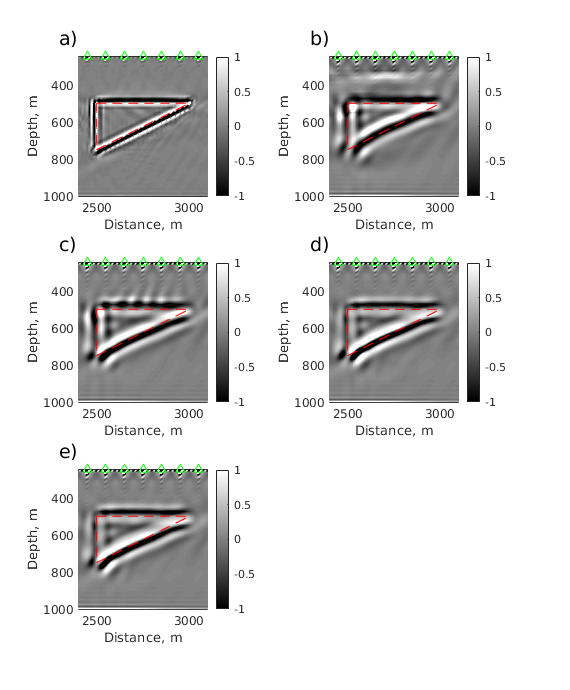


subplot(3,2,1)
pcolor(G.xx, G.zz, -100*FIMAGE(:,:,5)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(2300,150,'a)','FontSize',14)

subplot(3,2,2)
pcolor(G.xx, G.zz, FIMAGE(:,:,1)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(2300,150,'b)','FontSize',14)

subplot(3,2,3)
pcolor(G.xx, G.zz, FIMAGE(:,:,2)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(2300,150,'c)','FontSize',14)

subplot(3,2,4)
pcolor(G.xx, G.zz, FIMAGE(:,:,3)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(2300,150,'d)','FontSize',14)

subplot(3,2,5)
pcolor(G.xx, G.zz, FIMAGE(:,:,4)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
text(2300,150,'e)','FontSize',14)

%colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
colormap('gray')

figure(1)
fig = figure('Position', [900 400 280 230])

fig =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


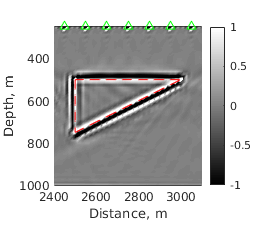

pcolor(G.xx, G.zz, -100*FIMAGE(:,:,5)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(2)
fig = figure('Position', [900 400 280 230])

fig =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


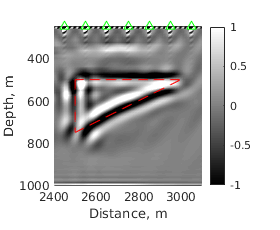

pcolor(G.xx, G.zz, FIMAGE(:,:,1)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(3)
fig = figure('Position', [900 400 280 230])

fig =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


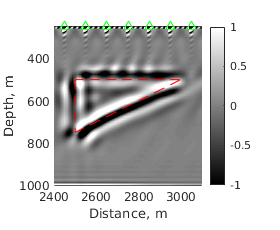

pcolor(G.xx, G.zz, FIMAGE(:,:,2)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(4)
fig = figure('Position', [900 400 280 230])

fig =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


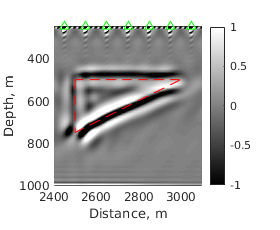

pcolor(G.xx, G.zz, FIMAGE(:,:,3)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(5)
fig = figure('Position', [900 400 280 230])

fig =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


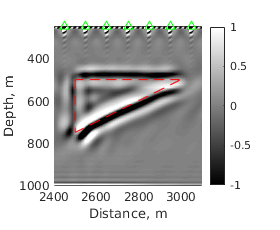

pcolor(G.xx, G.zz, FIMAGE(:,:,4)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--r', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--r', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--r', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(11)
fig = figure('Position', [900 400 280 230])

fig =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


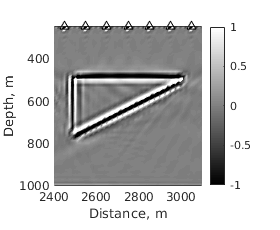

pcolor(G.xx, G.zz, -100*FIMAGE(:,:,5)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--w', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--w', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--w', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(21)
fig = figure('Position', [900 400 280 230])

fig =   Figure (33) with properties:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


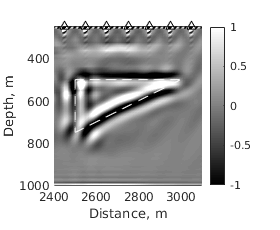

pcolor(G.xx, G.zz, FIMAGE(:,:,1)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--w', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--w', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--w', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(32)
fig = figure('Position', [900 400 280 230])

fig =   Figure (34) with properties:

      Number: 34
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


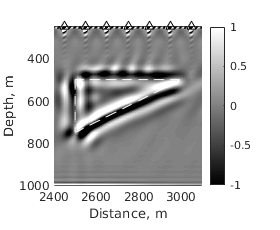

pcolor(G.xx, G.zz, FIMAGE(:,:,2)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--w', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--w', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--w', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(42)
fig = figure('Position', [900 400 280 230])

fig =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


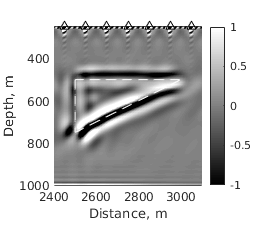

pcolor(G.xx, G.zz, FIMAGE(:,:,3)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--w', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--w', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--w', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')


figure(52)
fig = figure('Position', [900 400 280 230])

fig =   Figure (36) with properties:

      Number: 36
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 280 230]
       Units: 'pixels'

  Show all properties


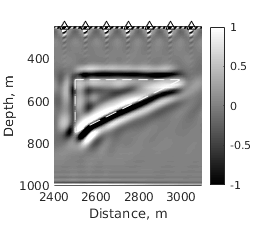

pcolor(G.xx, G.zz, FIMAGE(:,:,4)');
shading interp
caxis([-1 1])
set(gca,'YDir', 'reverse')
hold on
plot(acq.sx, acq.sz, 'k^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'blackv')
plot(linspace(2500,3000,250), linspace(750,500,250), '--w', 'LineWidth',0.5); 
plot(linspace(2500,3000,250), linspace(500,500,250), '--w', 'LineWidth',0.5);
plot(linspace(2500,2500,250), linspace(500,750,250), '--w', 'LineWidth',0.5);
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([2400 3100 250 1000]); 
xlabel('Distance, m')
ylabel('Depth, m')
colorbar
colormap('gray')